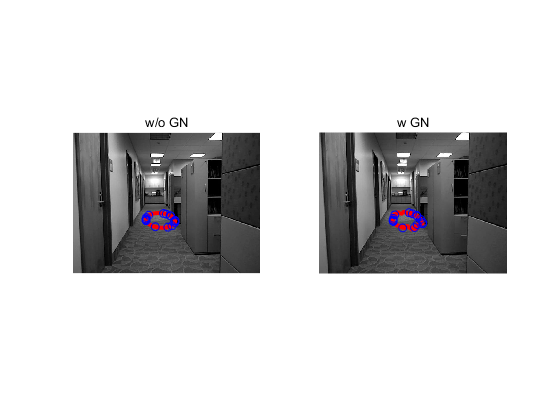

% KAIST EE667
% Multiple View Geometry, 2021 Spring
% HW2: Conic Fitting
%
% Student ID     : 20213569
% Name           : Byeongin Joung
% Date           : 2021.04.08
% Matlab Ver.    : R2021a
%

% Set All parameter
% Conic, hyperbola or ellipse,
% sigma(for gaussian noise), gaussian noise
% ellipse will be only if hyperbola = 0.
clear all
close all
warning('off', 'all')
comp = [50, 3, 300, 2, 25, 300];   % components of Conic
hyperbola = 0;                  % Set hyperbola
num_points = 100;
params_points = linspace(-3.14, 3.14, num_points);
sigma = 10;                     % variance for gaussian noise
gn = sqrt(sigma)*randn(size(params_points)); % gaussian noise

% Load RGB Images
img1 = imread('HW2_20213569_1.jpg');

% Transform to gray-scale image and get size
img1_gray = rgb2gray(img1);
h = size(img1, 1);
w = size(img1, 2);

% Get samples from 'with Gaussian Noise' figure
r = randperm(100);
num_rand = 15;
target = zeros(num_rand,1);
target_gn = zeros(num_rand,1);
for i=1:num_rand
    target(i) = params_points(r(i));
    target_gn(i) = gn(r(i));
end

% Plot gray img with conic
figure()
subplot(1,2,1), imshow(img1_gray), hold on % w/o Gaussian Noise
if hyperbola == 1  % plot both side of hyperbola
    x = comp(1) * cosh(params_points) + comp(2) * sinh(params_points) + comp(3);
    y = comp(4) * cosh(params_points) + comp(5) * sinh(params_points) + comp(6);
    plot(x,y, -x, y, "LineWidth", 3, "Color", 'red')
else               % Ellipse
    x = comp(1) * cos(params_points) + comp(2) * sin(params_points) + comp(3);
    y = comp(4) * cos(params_points) + comp(5) * sin(params_points) + comp(6);
    plot(x,y, "LineWidth", 3, "Color", 'red')
    x_source = comp(1) * cos(target) + comp(2) * sin(target) + comp(3);
    y_source = comp(4) * cos(target) + comp(5) * sin(target) + comp(6);
    plot(x_source,y_source, 'o', "Color", 'blue')
end
title('w/o GN')
subplot(1,2,2), imshow(img1_gray), hold on % w Gaussian Noise
if hyperbola == 1
    x = comp(1) * cosh(params_points) + comp(2) * sinh(params_points) + comp(3);
    y = comp(4) * cosh(params_points) + comp(5) * sinh(params_points) + comp(6);
    plot(x,y, -x, y, "LineWidth", 3, "Color", 'red')
else
    x = comp(1) * cos(params_points) + comp(2) * sin(params_points) + comp(3) + gn;
    y = comp(4) * cos(params_points) + comp(5) * sin(params_points) + comp(6) + gn;
    plot(x,y, "LineWidth", 3, "Color", 'red')
    x_target = comp(1) * cos(target) + comp(2) * sin(target) + comp(3) + target_gn;
    y_target = comp(4) * cos(target) + comp(5) * sin(target) + comp(6) + target_gn;
    plot(x_target,y_target, 'o', "Color", 'blue')
end
title('w GN')

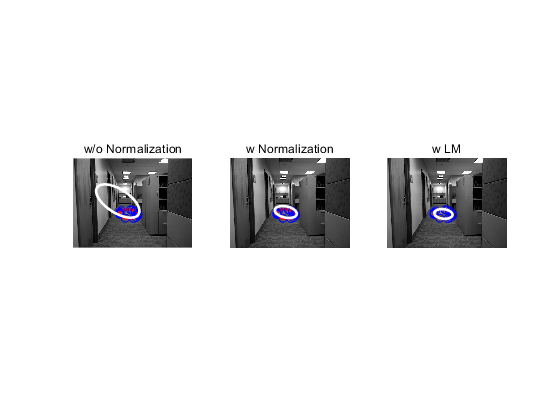

% Conic Fitting with DLT algorithm
% Inhomogeneous method to find H
tar = [x_target, y_target, ones(num_rand,1)];
src = [x_source, y_source, ones(num_rand,1)];

% set A to find init H
A = zeros(2*num_rand,9);
for i=1:num_rand
    A(2*i-1, 4:6, :) = -src(i,:);
    A(2*i-1, 7:9, :) = tar(i,2)*src(i,:);
    A(2*i, 1:3, :) = src(i,:);
    A(2*i, 7:9, :) = -tar(i,1)*src(i,:);
end

[~, ~, V] = svd(A);
V = transpose(V);
H = [V(9,1:3) V(9,4:6) V(9,7:9)];

result = A*transpose(H);
loss = sqrt(sum(result.^2))/sqrt(sum(H.^2));

x = comp(1) * cos(params_points) + comp(2) * sin(params_points) + comp(3);
y = comp(4) * cos(params_points) + comp(5) * sin(params_points) + comp(6);
origin = [transpose(x), transpose(y), transpose(ones(size(y)))];
H_mat = [H(1:3); H(4:6); H(7:9)];
homography = H_mat*transpose(origin);
homography = homography(1:2,:)./homography(3,:);

% Conic Fitting with Normalized DLT algorithm

% Normalization
m = [w/2 h/2];
s = h+w;
T_src = [[s 0 m(1)]; [0 s m(2)]; [0 0 1]];
T_tar = [[s 0 m(1)]; [0 s m(2)]; [0 0 1]];

src_norm = transpose(T_src\transpose(src));
tar_norm = transpose(T_tar\transpose(tar));

A_norm = zeros(2*num_rand,9);
for i=1:num_rand
    A_norm(2*i-1, 4:6, :) = -src_norm(i,:);
    A_norm(2*i-1, 7:9, :) = tar_norm(i,2)*src_norm(i,:);
    A_norm(2*i, 1:3, :) = src_norm(i,:);
    A_norm(2*i, 7:9, :) = -tar_norm(i,1)*src_norm(i,:);
end

[U, D, V] = svd(A_norm);
V = transpose(V);
H_norm = [V(9,1:3) V(9,4:6) V(9,7:9)];

result_norm = A_norm*transpose(H_norm);
loss_norm = sqrt(sum(result_norm.^2))/sqrt(sum(H_norm.^2));
% Denormalization
H_mat_norm = [H_norm(1:3); H_norm(4:6); H_norm(7:9)];
H_mat_norm = T_tar*H_mat_norm/T_src;
H_mat_norm = H_mat_norm/H_mat_norm(3,3);

homography_norm = H_mat_norm * transpose(origin);
homography_norm = homography_norm(1:2,:)./homography_norm(3,:);

% Conic fitting with Levenberg-Marquardt method by using sampson error
% homography를 optmize하는 방식으로 진행할 것.
% error는 reprojection error를 바탕으로 하는데, 어짜피 이게 homography임.
% good. everything will be fine.

[epsilon, jacobian] = GetJacobian(H_mat_norm, src, tar);
JTJ = transpose(jacobian)*jacobian;
JTe = transpose(jacobian)*epsilon;
delta = -transpose(JTJ\JTe);
H_update = [H_mat_norm(1,1:3)+delta(1:3); H_mat_norm(2,1:3)+delta(4:6); H_mat_norm(3,1:3)+delta(7:9)];
H_update = H_update/H_update(3,3);

epsilon = jacobian*transpose([H_update(1:3), H_update(4:6), H_update(7:9)]);
sampson_init = transpose(epsilon)*inv(jacobian*transpose(jacobian))*epsilon;

thres_delta = sqrt(sum(delta.^2,'all'));
threshold = 10;

max_iter = 30;
iter = 0;
while thres_delta > threshold
    [epsilon, jacobian] = GetJacobian(H_update, src, tar);
    JTJ = transpose(jacobian)*jacobian;
    JTe = transpose(jacobian)*epsilon;
    delta = -transpose(JTJ\JTe);
    H_update = [H_update(1,1:3)+delta(1:3); H_update(2,1:3)+delta(4:6); H_update(3,1:3)+delta(7:9)];
    H_update = H_update/H_update(3,3);
    epsilon = jacobian*transpose([H_update(1:3), H_update(4:6), H_update(7:9)]);
    sampson_init = transpose(epsilon)*inv(jacobian*transpose(jacobian))*epsilon;

    thres_delta = sqrt(sum(delta.^2,'all'));
    iter = iter + 1;
    
    if iter > max_iter
        break
    end
end

homography_LM = H_update * transpose(origin);
homography_LM = homography_LM./homography_LM(3,:);

figure()
subplot(1,3,1)
imshow(img1_gray), hold on, title('w/o Normalization')
if hyperbola == 1  % plot both side of hyperbola
    x = comp(1) * cosh(params_points) + comp(2) * sinh(params_points) + comp(3);
    y = comp(4) * cosh(params_points) + comp(5) * sinh(params_points) + comp(6);
    plot(x,y, -x, y, "LineWidth", 3, "Color", 'red')
else               % Ellipse
    plot(x, y, "LineWidth", 2, "Color", "red");
    x_source = comp(1) * cos(target) + comp(2) * sin(target) + comp(3);
    y_source = comp(4) * cos(target) + comp(5) * sin(target) + comp(6);
    plot(x_source,y_source, 'o', "Color", 'blue');
    plot(homography(1,:), homography(2,:), "LineWidth", 2, "Color", 'white');
end
subplot(1,3,2)
imshow(img1_gray), hold on, title('w Normalization')
if hyperbola == 1  % plot both side of hyperbola
    x = comp(1) * cosh(params_points) + comp(2) * sinh(params_points) + comp(3);
    y = comp(4) * cosh(params_points) + comp(5) * sinh(params_points) + comp(6);
    plot(x,y, -x, y, "LineWidth", 3, "Color", 'red')
else               % Ellipse
    plot(x, y, "LineWidth", 2, "Color", "red");
    x_source = comp(1) * cos(target) + comp(2) * sin(target) + comp(3);
    y_source = comp(4) * cos(target) + comp(5) * sin(target) + comp(6);
    plot(x_source,y_source, 'o', "Color", 'blue');
    plot(homography_norm(1,:), homography_norm(2,:), "LineWidth", 2, "Color", 'white');
end
subplot(1,3,3)
imshow(img1_gray), hold on, title('w LM')
if hyperbola == 1  % plot both side of hyperbola
    x = comp(1) * cosh(params_points) + comp(2) * sinh(params_points) + comp(3);
    y = comp(4) * cosh(params_points) + comp(5) * sinh(params_points) + comp(6);
    plot(x,y, -x, y, "LineWidth", 3, "Color", 'red')
else               % Ellipse
    plot(x, y, "LineWidth", 2, "Color", "red");
    x_source = comp(1) * cos(target) + comp(2) * sin(target) + comp(3);
    y_source = comp(4) * cos(target) + comp(5) * sin(target) + comp(6);
    plot(x_source,y_source, 'o', "Color", 'blue');
    plot(homography_LM(1,:), homography_LM(2,:), "LineWidth", 2, "Color", 'white');
    %plot(tar_LM(:,1), tar_LM(:,2), "LineWidth", 2, "Color", 'white');
end